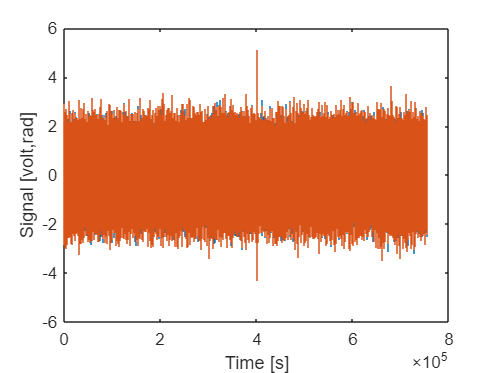

clear all
load("experiment_26_3.mat")
%load("experiment_26_3_LOADSIDE.mat")

% Plot the measurement
figure(1); clf(1);
stairs(d); hold on; stairs(u);
xlabel('Time [s]'); ylabel('Signal [volt,rad]');
hold off


%data analysis
fs = 4000 %[Hz]

fs = 4000

stepsize = 1/fs %[s]

stepsize = 2.5000e-04

max_freq = log10(fs/2) 

max_freq = 3.3010

%t_end = N_samples/fs

%removing uselss data 
N_trash = 1000; 
u = u(N_trash:end)

u =    -0.4806
    0.2612
    1.4236
    0.9691
    0.4528
    0.4695
    0.5850
    0.1154
    0.2714
   -0.2685


d = d(N_trash:end)

d =    -0.9298
   -0.1881
    0.9806
    0.5293
    0.0130
    0.0297
    0.1451
   -0.3181
   -0.1558
   -0.6957


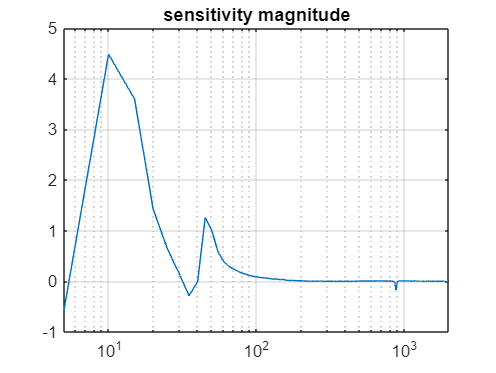


%window settings
min_freq = 5; %[Hz/s] lowest desired sampling frequency
windowsize = 1/min_freq; %[s] window size in seconds

nfft = round(windowsize/stepsize); %window size in data points 
n_overlap = round(nfft/2);

%Tf estimate
[Sud, F] = tfestimate(d,u,hann(nfft),n_overlap,nfft,fs); %cross spectral power density
Sdd = pwelch(d,hann(nfft)); %spectral power disturbance
Suu = pwelch(u,hann(nfft)); %spectral power input
%S =  Sud./Sdd; %sensitivity function
S = Sud;
semilogx(F,mag2db(abs(S)))
title("sensitivity magnitude")
grid on

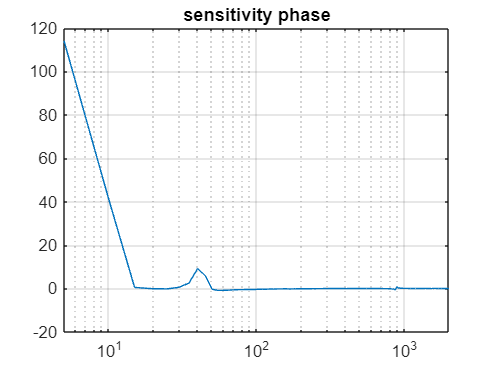


semilogx(F,angle(S)/pi*180)
title('sensitivity phase')
grid on

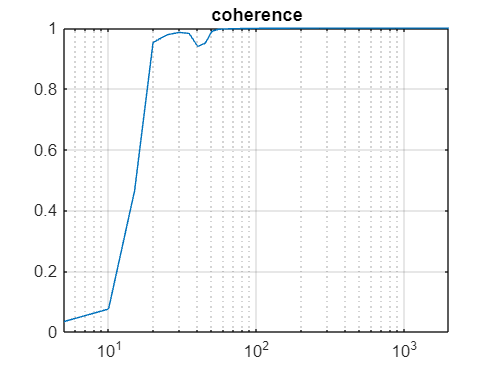


%plotting coherence 
[coherence_ry, f] = mscohere(d,u,hann(nfft),[],nfft,fs);
semilogx(f,coherence_ry)
title('coherence')
grid on 

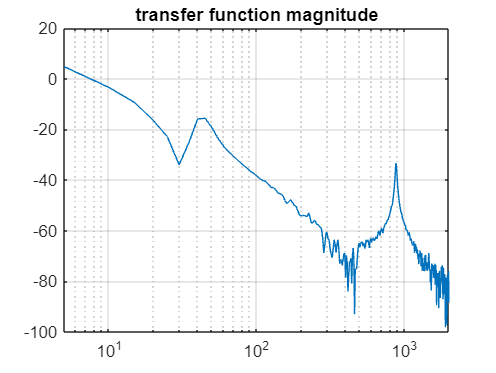

    
%plotting open loop transfer function
L = 1./S - 1;
semilogx(F,mag2db(abs(L)))
title('transfer function magnitude')
grid on

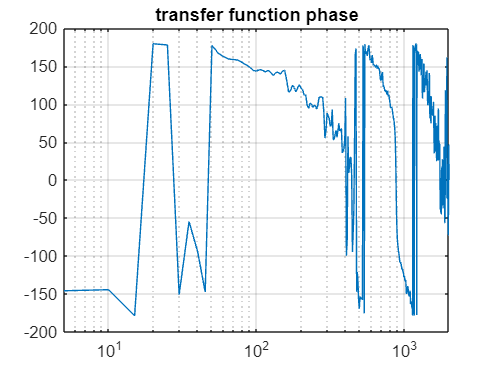


semilogx(F,angle(L)/pi*180)
title('transfer function phase')
grid on